# Son 2: Enregistrement de voix humaine

Tel que pour le son 1, un bruit blanc gaussien sera ajouté à un enregistrement de voix humaine. Les informations pertinentes à savoir pour cet exercise sont : 

-Le bruit blance se situe également sur l,ensemble des toutes le fréquences.

-La voix humaine se situe majoritairement entre 20 Hz et 600 Hz.

-L'oreille humaine peut entendre jusqu'à 22 kHz

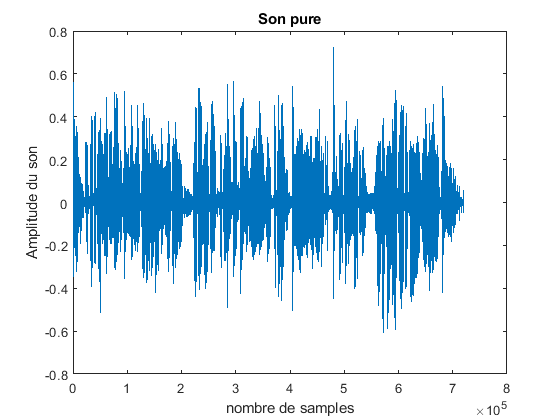

%% Exemple avec un signal de voix

% le but est

clear all;
close all;
clc;
format short eng


used_time = 15; % temps en secondes

delay_time = 35 ;% temps en delais en [s] laisser écouler x secs avant échantillionnage
frequencyLimits = [0 24000]; % [Hz]   Seuil de l'audition humaine approx

%% Extraction du signal

% [son_1_sans_perturbation,sampleRate] = audioread('raspoutine.mp4'); Used to
% exctract sampleRate from original file

% sampleRate est statique a 48000 et sera donc declare de facon staique
sampleRate = 48000;
%time_total = (length(son_1_sans_perturbation)/ sampleRate); % temps en secondes

delay_points = delay_time*sampleRate;

cropped_sound = audioread('raspoutine.mp4',[(1+delay_points) (sampleRate*used_time+delay_points)]);

sample_point=1:1:length(cropped_sound);
%% ajout du bruit gaussien
range = 200;
SNR = 0; % signal-to-noise ratio


% Le son sera perturbé deux fois afin d'augmenter la quantité de bruit 
son_1_avec_perturbation = awgn(cropped_sound, SNR,  'measured');
son_1_avec_perturbation = awgn(son_1_avec_perturbation, SNR,  'measured');




%% Plots PURE sans perturbation
figure
plot(sample_point,cropped_sound(:,1));
title('Son pure')
xlabel('nombre de samples')
ylabel('Amplitude du son')

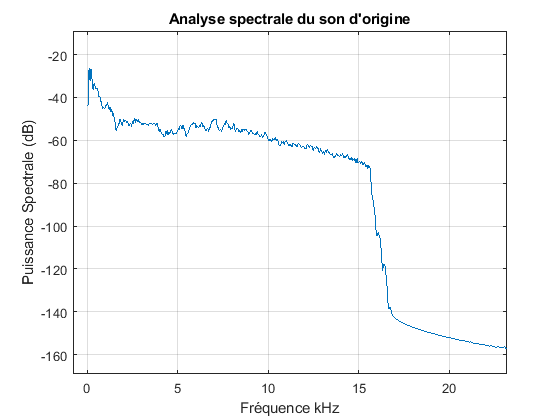



figure
SpectralAnalyser(cropped_sound(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son d''origine')

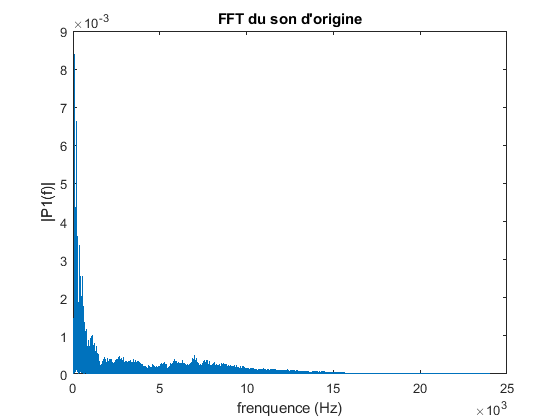


figure
fftPlotter(cropped_sound(:,1),sampleRate);
title('FFT du son d''origine')

## Plots avec perturbation

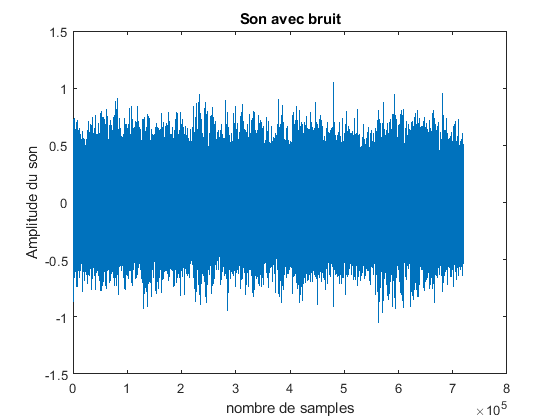


figure
plot(sample_point,son_1_avec_perturbation(:,1));
title('Son avec bruit')
xlabel('nombre de samples')
ylabel('Amplitude du son')

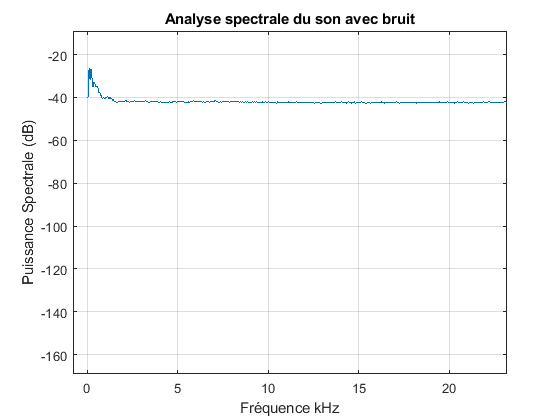


figure
SpectralAnalyser(son_1_avec_perturbation(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son avec bruit')

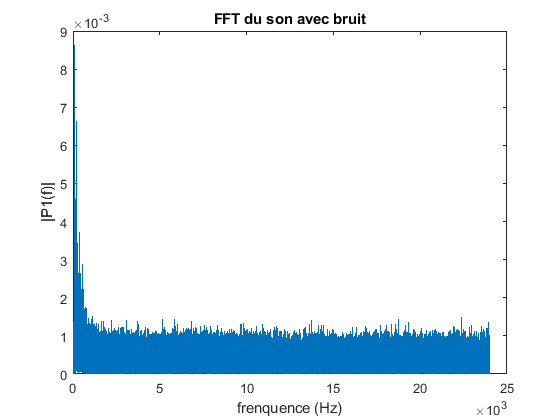


fftPlotter(son_1_avec_perturbation(:,1),sampleRate)
title('FFT du son avec bruit')


%sound(son_1_avec_perturbation,sampleRate);

Dans ce cet section, les fréquences à isoler ainsi que l'origine des perturbations sont connues. Il est donc facile de savoir quelles fréquences isoler et quelles couper. Cependant, il peut arriver que le son à isoler ainsi que l'origine du bruit soit inconnue. Les approches suivantes vont supposer que le bruit ainsi que les fréquences à isoler sont inconnue.Afin d'avoir une meilleur idée du son à isoler, nous proposons donc d'appliquer d'abords un filtre passe-bas. Ce premier filtre devrait permettre d'isoler les hautes fréquences et ainsi, permettre d'avoir une meilleur idée des fréquences voulu et des frequences parasites.

En regardant la fft du son avec bruit il est possible de voir des peaks jusqu'à environ 800 Hz avant que les son s'entremêle avec les perturbations.

Cependant, en regardant l'analyse spectrale, on peut  voir que le signal possède une puissance jusqu'a envoron 1400 Hz où le signal se stabilise à une puissance de -40 dB.

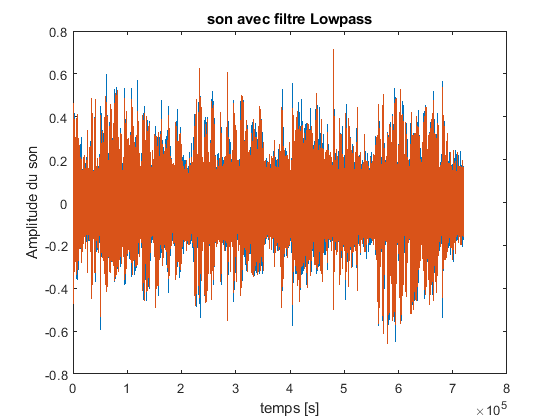



%% Application d'un filtre simple (lowpass)
freq_coupure_lowpasse = 1300; % les frequences de coupures sont determin/es a partir de la FFT

son_1_filtre_lowpass = lowpass(son_1_avec_perturbation,freq_coupure_lowpasse,sampleRate);

figure
plot(sample_point,son_1_filtre_lowpass)
title('son avec filtre Lowpass')
xlabel('temps [s]')
ylabel('Amplitude du son')

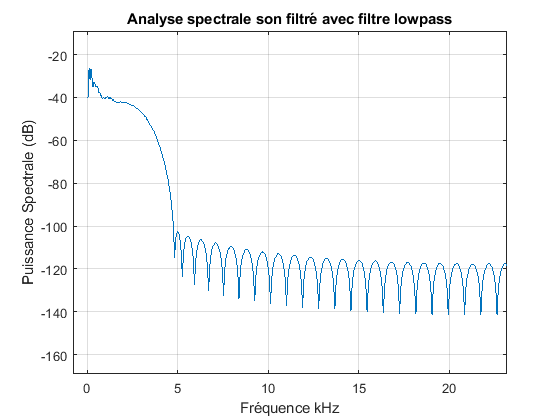


figure
SpectralAnalyser(son_1_filtre_lowpass(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre lowpass');

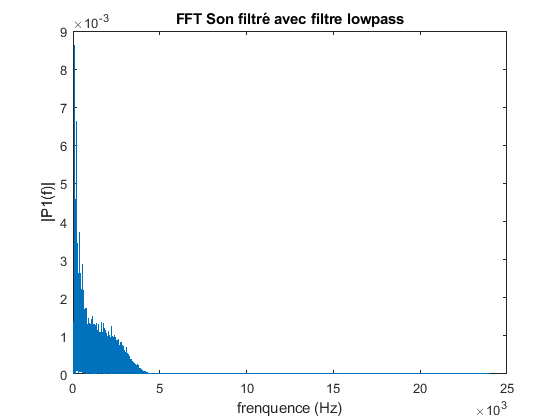


figure
fftPlotter(son_1_filtre_lowpass,sampleRate)
title('FFT Son filtré avec filtre lowpass');


%sound(son_1_filtre_lowpass,sampleRate);


 À l'écoute, l'application du filtre lowpass est démontre une amélioration de la qualtié du signal par rapport au signal bruité nous savons d'onqu que le signal se situe bel et bien dans la section de basses fréquences du spectre fréquenciel.

Sachant que le signal à isoler est composé de voix humaine. Il est possible d'avoir une idée de sa composition fréquenciel.

La vois humaine varie habituellement entre 20 Hz et 600 Hz.

Essayons un filtre passebande avec ces fréquences. 

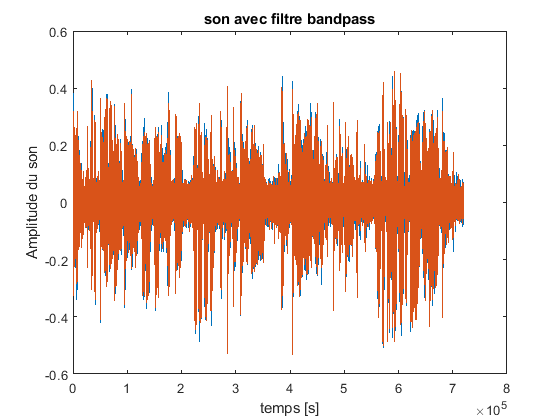

son_2_filtre_bandpass2 = bandpass(son_1_avec_perturbation,[40 600],sampleRate);




%% plot filtre bandpass

figure
plot(sample_point,son_2_filtre_bandpass2)
title('son avec filtre bandpass')
xlabel('temps [s]')
ylabel('Amplitude du son')

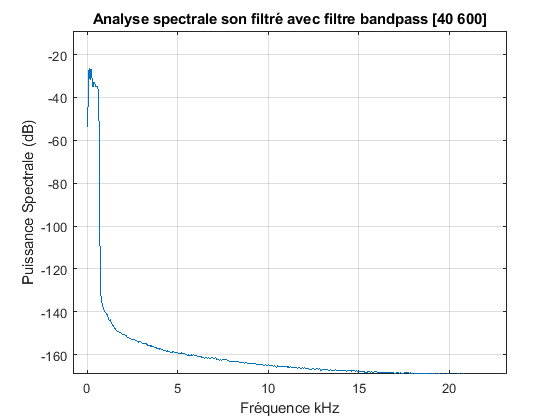


figure
SpectralAnalyser(son_2_filtre_bandpass2(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre bandpass [40 600]');

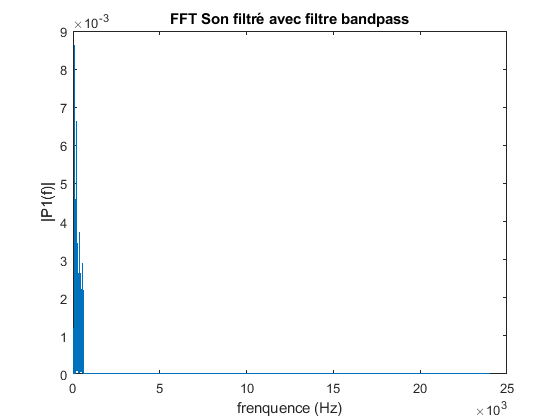


figure
fftPlotter(son_2_filtre_bandpass2,sampleRate)
title('FFT Son filtré avec filtre bandpass');

%hold on
%figure

%fft_passebande2 = fft(son_2_filtre_bandpass2);


Le bruit blanc est grandement  atténué. Cependant le bruit des voix semble un peu étouffé. appliquons un gain pour mieu entendre pour entendre un pei mieu.

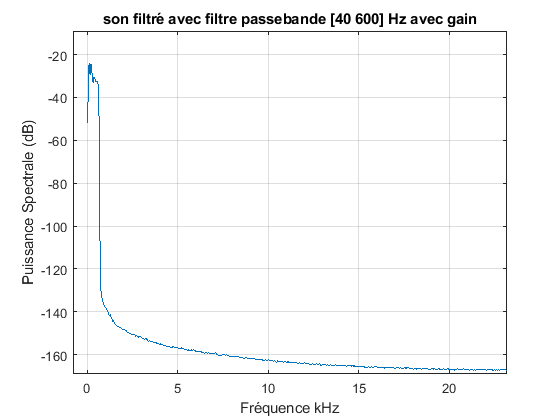

son_2_filtre_bandpass2_2 = son_2_filtre_bandpass2*1.3; % application d'un gain

figure
SpectralAnalyser(son_2_filtre_bandpass2_2,sampleRate,frequencyLimits,0,[0 15]);
title('son filtré avec filtre passebande [40 600] Hz avec gain')

## Comb filter



N     = 40 ;   % Order
BW    =  1000% Bandwidth

BW =      1.0000e+003


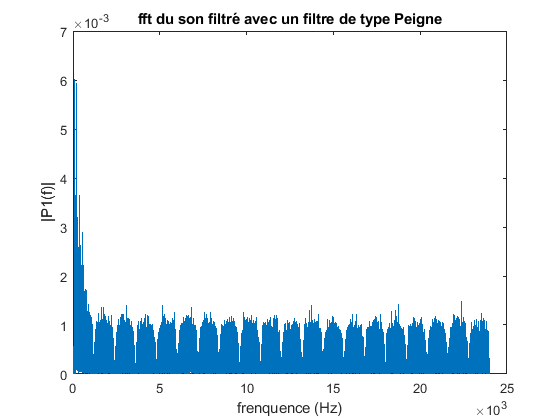

Apass = 3;    % Bandwidth Attenuation

[b, a] = iircomb(N,...
    BW/(sampleRate/2),...
    Apass, 'peak');


combFilt    = dfilt.df2(b, a);

resComb = filter(combFilt,son_1_avec_perturbation);
figure
fftPlotter(resComb,sampleRate);
title('fft du son filtré avec un filtre de type Peigne')

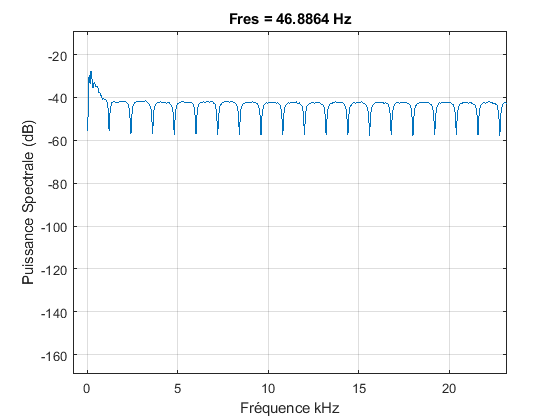


SpectralAnalyser(resComb(:,1),sampleRate,frequencyLimits,0,[0 15]);


%sound(resComb,sampleRate);



On peut voir que comme dans le cas du son 1, les filtres de type peignes ne sont pas au point pour filtrer un bruit gaussien. Comme pour le son 1, ces filtres (les filtres coup-bande) ne vont couper que certaines fréquences spécifiques, ce qui est peu utile dans ce ca si car les perturbations sont avec un bruit blanc. Cependant, dans le cas d'un bruit ambiant comme une perturbation 60 Hz à cause d'un courant AC dans les murs par exemple, le filtre coupes bande seraient très utiles.

## Application d'un filtre Chebychev

 Pour le son 1, Le filtre passeband de chebychev fut un grand succes. Essayns encore mais cette fois-ci  en appliquant les fréquences de coupures approximatives de la voix humaines.

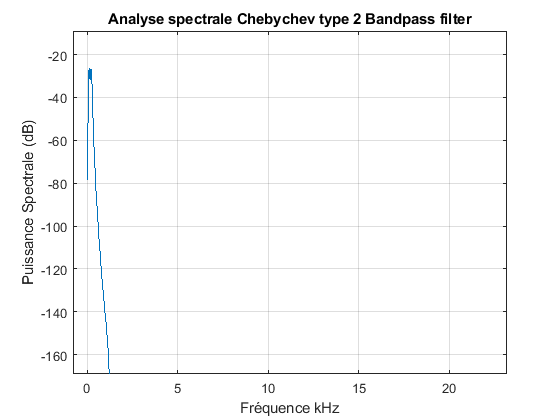

   
Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 1200;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 12; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb = filter(cheby2,son_1_avec_perturbation);

figure
SpectralAnalyser(resCheb,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter')

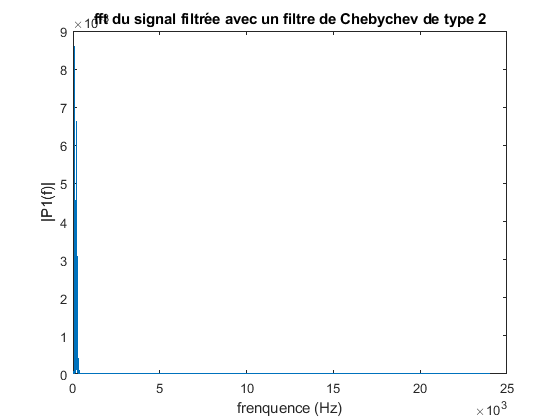

%xlim([0 20])
%ylim([-120 24])


%sound(resCheb,sampleRate);
figure
fftPlotter(resCheb,sampleRate)
title('fft du signal filtrée avec un filtre de Chebychev de type 2')

Nous avons maintant une réponse. Essayons maintenant un filtre coupe-Bande de type qui est lui aussi répotué pour avoir une bande passnante stable sans ripple.

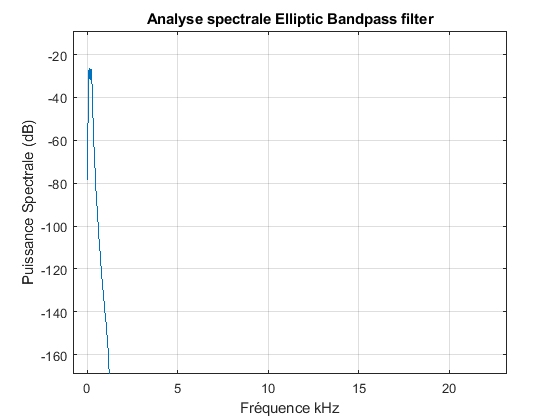

%Bandpass Elliptic Filter
%View MATLAB Command

%Design a 20th-order elliptic bandpass filter with a lower passband frequency of 500 Hz and a higher passband frequency of 560 Hz. Specify a passband ripple of 3 dB, a stopband attenuation of X dB, and a sample rate of Y Hz. Use the state-space representation. Design an identical filter using designfilt.

%[A,B,C,D] = ellip(10,3,40,[500 560]/750);
d = designfilt('bandpassiir','FilterOrder',filtOrder, ...
    'PassbandFrequency1',Fstop1,'PassbandFrequency2',Fstop2, ...
    'PassbandRipple',3, ...
    'StopbandAttenuation1',40,'StopbandAttenuation2',Astop, ...
    'SampleRate',sampleRate);

resEllip= filter(d,son_1_avec_perturbation);


figure
SpectralAnalyser(resCheb,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Elliptic Bandpass filter')

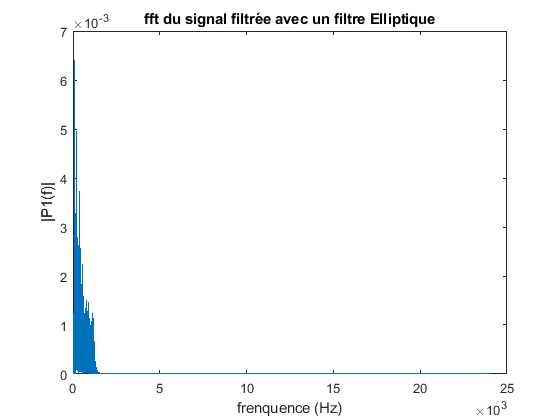



figure
fftPlotter(resEllip,sampleRate);
title('fft du signal filtrée avec un filtre Elliptique')

## comparing Chebychev 2 and Elliptic bandpass filters

   Savons d'un pont de vue théorique que dans ce scénrio spécifique, le filttre de type chebychev de type 2 est une meilleur option pour ce type de problème à cause de sa pande passante applatit et sans ripple. 

Comparons ce filtre avec un avec un filtre qui est est reconnue pour avoir une la meilleure vitesse de transition. Rappelons que d'un point du vue théorique une vitesse de transition est inutile pour isoler une voix humaine car la voix humaine possède une gamme de fréquence qui n'est pas fix. Les plus grands avantages de filtres Eliiptiques sont doncs inutils.

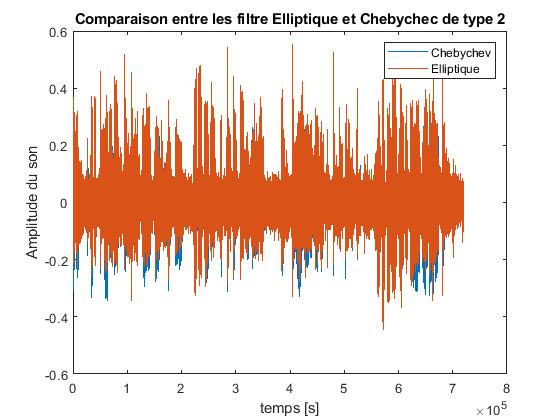

figure
plot(sample_point,resCheb(:,1));
hold on;
plot(sample_point,resEllip(:,1));
title('Comparaison entre les filtre Elliptique et Chebychec de type 2')
xlabel('temps [s]')
ylabel('Amplitude du son')
legend('Chebychev','Elliptique');
hold off;

## Wavelet analysisis

Comme 6iem filtre essayons quelque chose de différent. L'approche suivante est basé sur l'anayse par wavelets tel que définie [[https://www.hpl.hp.com/hpjournal/94dec/dec94a6a.pdf](https://www.hpl.hp.com/hpjournal/94dec/dec94a6a.pdf) ]. Contrairement aux séries de Fourier qui font du dévloppement sous fomre de série trigonométriques, les wavelets procède au développement de fonctions sous forme de translations et de dilatations. Le résultat est exprimé sous forme temporel ainsi que fréquencielle. En pratique les wavelets sont utilisées pour traiter des signaux qui sont non stationnaires telque la voix. 

L'approche par wavelet as permis certaines avancés dans la réduction de bruit. par machine learning. 

datsignal = son_1_avec_perturbation(:,1) ;

audiowrite('datsig.wav',datsignal,sampleRate)

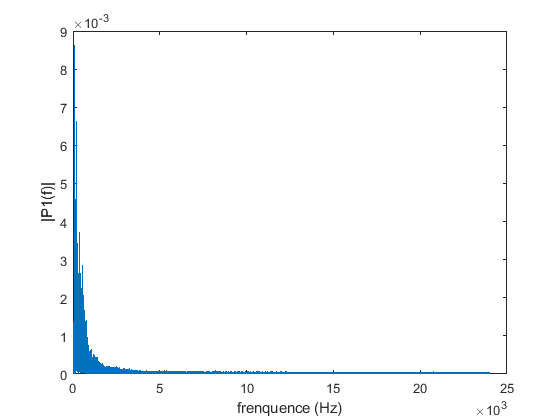


resDenoise = wdenoise(datsignal,5, ...
    'Wavelet', 'sym8', ...
    'DenoisingMethod', 'minimax',...
    'ThresholdRule', 'Hard', ...
    'NoiseEstimate', 'LevelDependent');

fftPlotter(resDenoise,sampleRate);